# Clasificación de Actividades Humanas Usando Aprendizaje Automático

Este es un ejemplo de aprendizaje supervisado.  

Los datos de sensores de actividad humana contienen observaciones derivadas de mediciones tomadas por sensores en teléfonos inteligentes que llevan las personas mientras realizan seis actividades diferentes: Caminar, Sentarse, Acostarse, Estar de Pie, Subir Escaleras y Bajar Escaleras.  

El objetivo de este ejemplo es construir un clasificador que pueda identificar automáticamente el tipo de actividad a partir de las mediciones de los sensores.** En este ejemplo de aprendizaje supervisado, trabajaremos con datos y características etiquetadas.**  

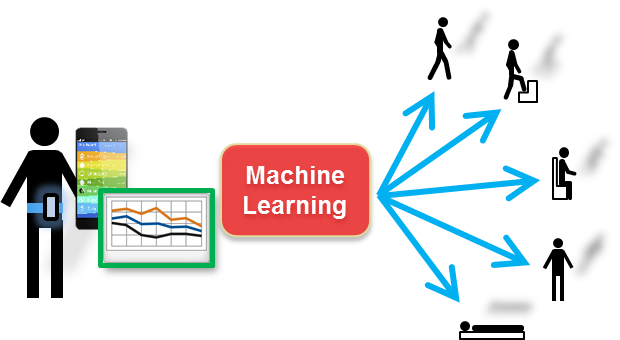

## 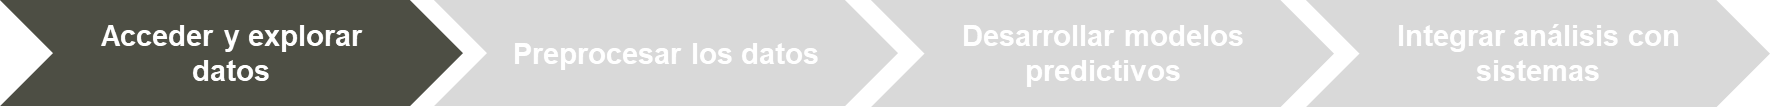

## Leer los datos

Cargaremos los datos en bruto llamados `rawSensorData`, que contienen **6 variables**, cada una representando mediciones de un sensor diferente (componentes x, y, z de un acelerómetro y componentes x, y, z de un giroscopio). La variable `trainActivity` contiene las etiquetas reales relacionadas a la actividad realizada.  

load('rawSensorData_train.mat')

Deberías ver entonces las 7 variables en el espacio de trabajo.  

Cada fila representa una observación (128 puntos de datos = 128 columnas).

## Mostrar resumen de datos

Muestra los datos originales del sensor.

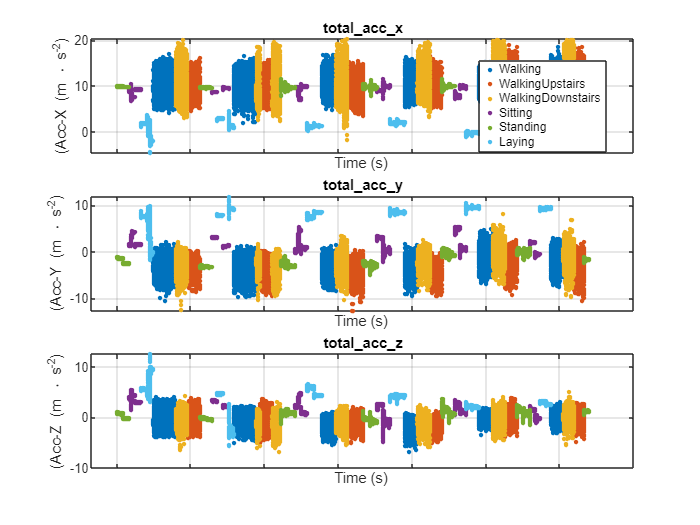

plotRawSensorData(total_acc_x,total_acc_y,total_acc_z,trainActivity,1000);

## 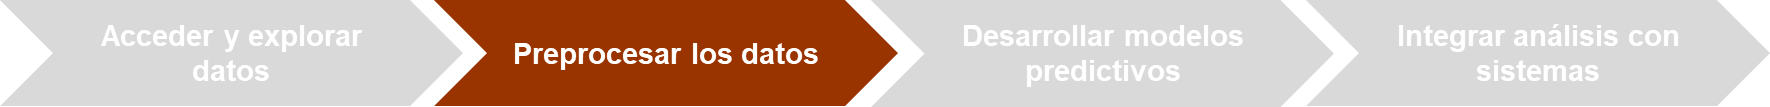

## **Preprocesar los datos**

Debido a la gran cantidad de puntos de datos individuales, es difícil agrupar las actividades. Por esta razón, reduciremos el número de puntos de datos en cada observación calculando el valor medio y la desviación estándar. Esto puede considerarse una reducción de la dimensionalidad.

Primero, calculemos la media ([mean](https://uk.mathworks.com/help/matlab/ref/mean.html)) y la desviación estándar ([std](https://uk.mathworks.com/help/matlab/ref/std.html)) y guardémoslas en un solo arreglo.

accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% Combinamos en un solo arreglo
ActivityDataTrain = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% Limpiar variables (para mantener el espacio de trabajo limpio)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## Explorar los datos de entrenamiento y prueba

### Datos de entrenamiento  

Al observar el resumen de los datos de entrenamiento, podemos ver que tenemos aproximadamente 1000 muestras para cada actividad.

summary(trainActivity)

trainActivity: 7352×1 categorical
     Walking                1226 
     WalkingUpstairs        1073 
     WalkingDownstairs       986 
     Sitting                1286 
     Standing               1374 
     Laying                 1407 
     <undefined>               0 


### Datos de prueba

Pasaremos el conjunto de datos de prueba (test data) por nuestro modelo para evaluarlo después del entrenamiento. El conjunto de datos de prueba debe tener el mismo formato que el conjunto de datos de entrenamiento. Por lo tanto, necesitamos extraer las mismas características que hicimos con los datos de entrenamiento. Así que realizaremos los mismos pasos que para los datos de entrenamiento.  

El conjunto de datos de prueba contiene 2947 muestras y aproximadamente 500 muestras para cada actividad.  

**Nota: Cargar los datos de prueba sobrescribirá las variables de los datos de entrenamiento (total_acc_x, etc.), ya que tienen los mismos nombres.**

load('rawSensorData_test.mat')
summary(testActivity)

testActivity: 2947×1 categorical
     Walking                496 
     WalkingUpstairs        471 
     WalkingDownstairs      420 
     Sitting                491 
     Standing               532 
     Laying                 537 
     <undefined>              0 


accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% combine in one singel array
ActivityDataTest = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% clear variables (to keep workspace clean)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## 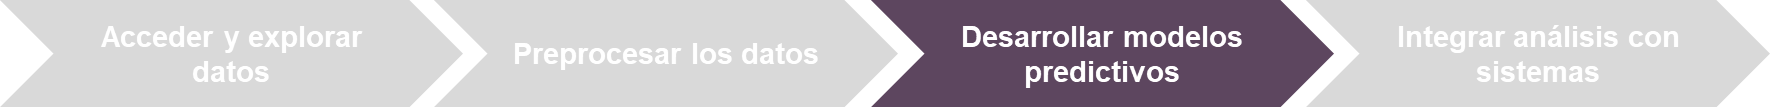

## Entrenar modelos  

Utiliza la aplicación **Classification Learner **para entrenar, comparar y seleccionar clasificadores de forma interactiva. Uno de los mayores desafíos en el aprendizaje automático es que existen muchos algoritmos diferentes que se pueden aplicar al mismo problema, y no hay forma de saber de antemano cuál funcionará mejor. La aplicación Classification Learner nos ofrece una manera sencilla de probar rápidamente muchas técnicas de modelado diferentes.  

Para abrir la aplicación Classification Learner, puedes ejecutar el siguiente comando o ir a APPS y hacer clic en 

classificationLearner

**Paso 1: **Hz clic en  *New Session* y elige *From Workspace*`.`

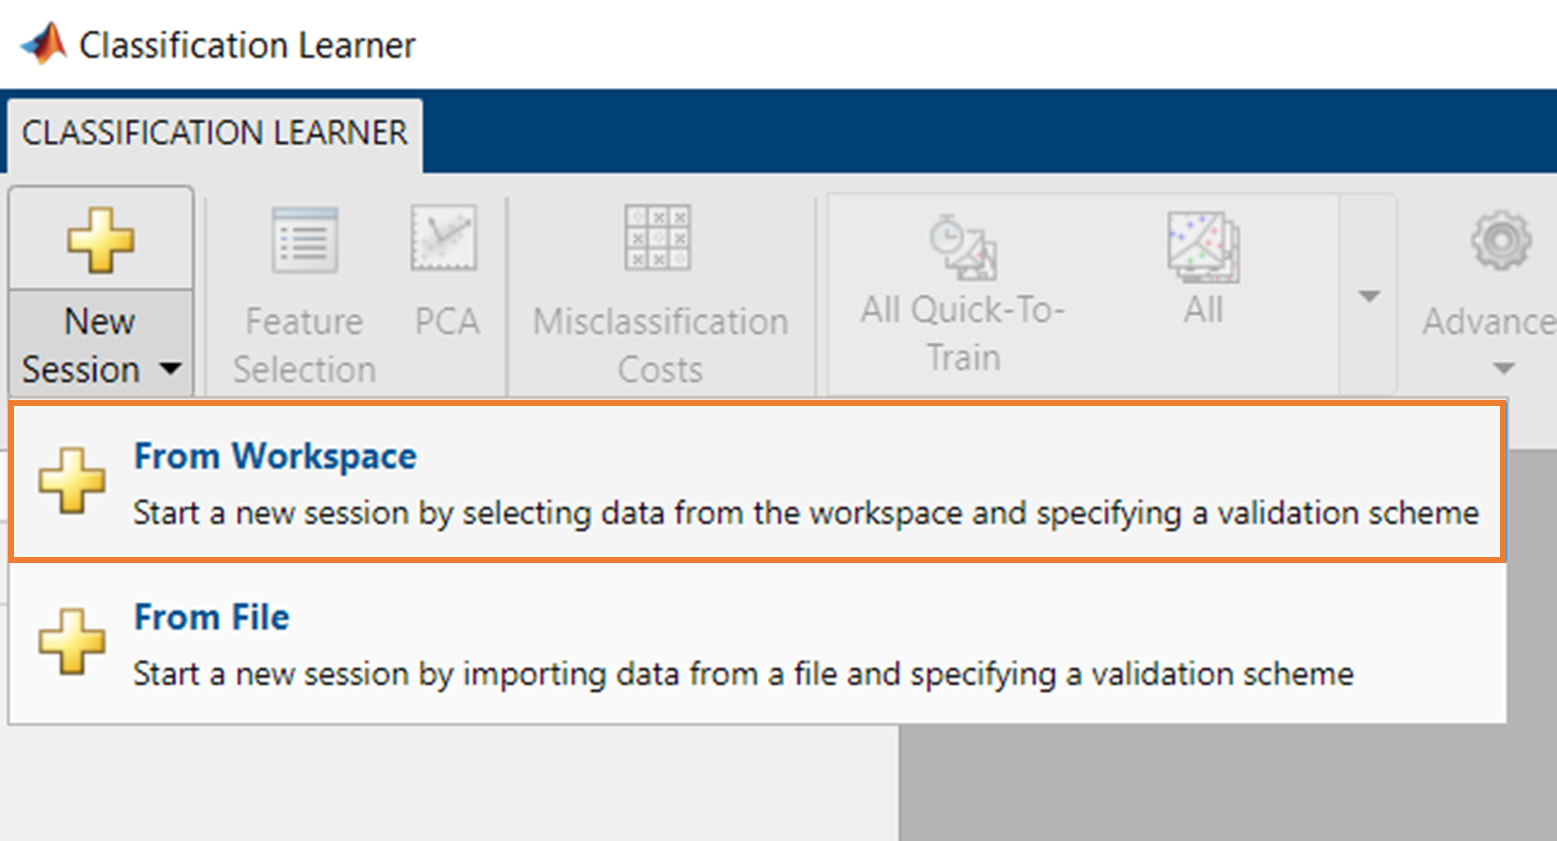

Elige la variable `ActivityDataTrain `del espacio de trabajo como tu *Data Set Variable*. Selecciona la variable de respuesta desde el espacio de trabajo y elige `trainActivity`. Mantén la sección de Validación tal como está (Validación cruzada con 5 particiones) y haz clic en Iniciar sesión.

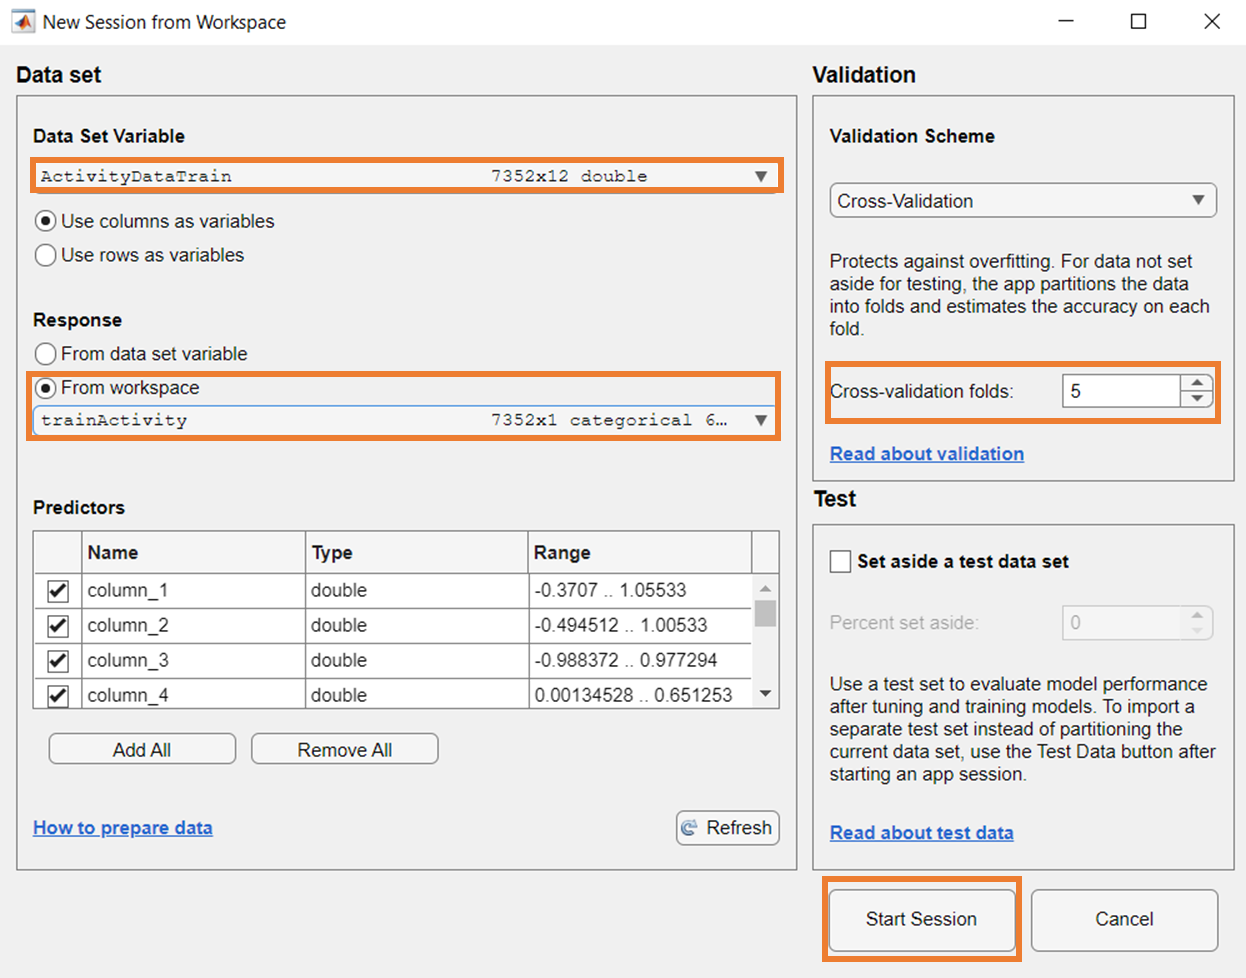

**Step 2:** En MODELS, elige* All Quick-To-Train* y comienza el entrenamiento haciendo clic en `Train ` . El entrenamiento debería tomar solo un par de segundos.

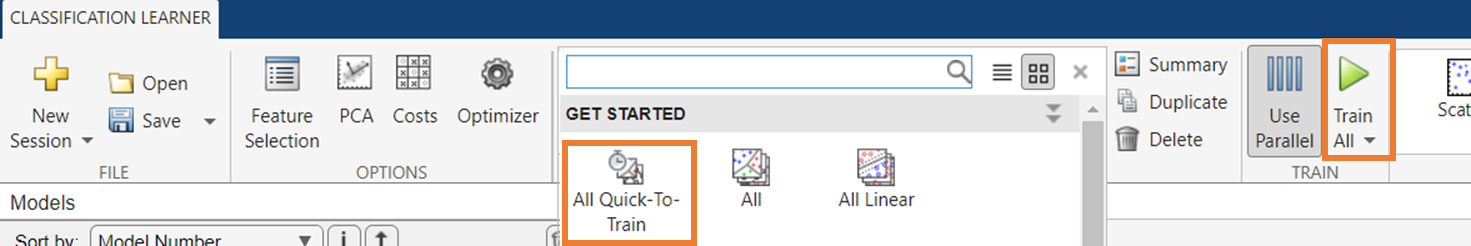

En la ventana de *Models*, deberías ver el progreso del entrenamiento y, cuando termine, la precisión final (de validación) de cada modelo. La mayor precisión se resalta en negrita. Tus resultados deberían verse similares a esto:

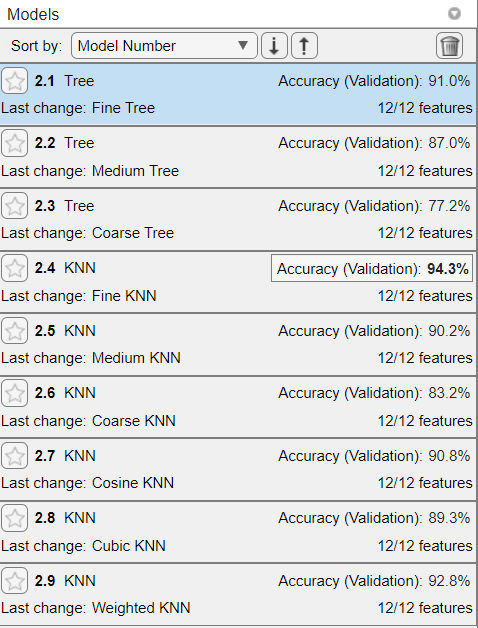

**Step 3:** Explora las matrices de confusión de cada modelo haciendo clic en el modelo individual y luego en *Confusion Matrix*. 

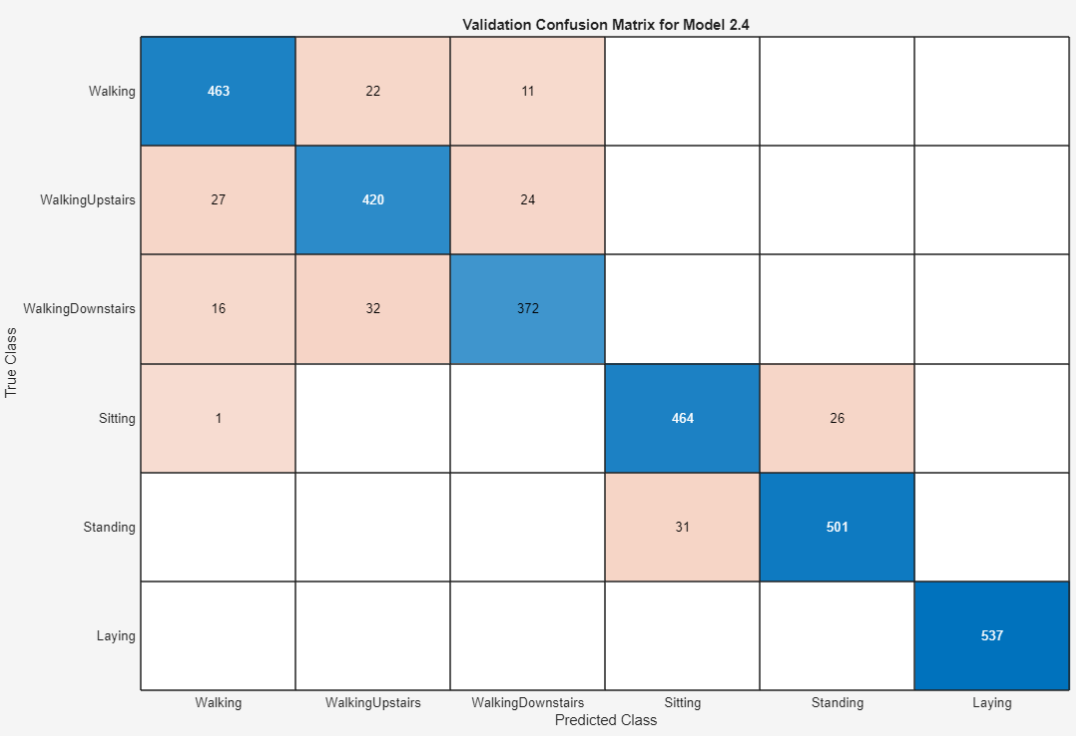

## Evaluar el modelo entrenado

Puedes evaluar el rendimiento de cada modelo con datos no vistos (datos de prueba).

Carga el conjunto de datos de prueba haciendo clic la pestaña TEST y luego en el menú desplegable de *Test Data* y eligiendo *From Workspace*. Selecciona `ActivityDataTest` como *Test Data Set Variable *(asegúrate de que la variable de respuesta sea `testActivity`) y haz clic en Import.

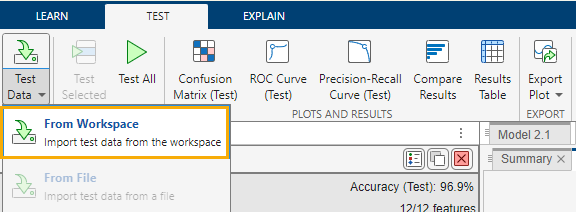

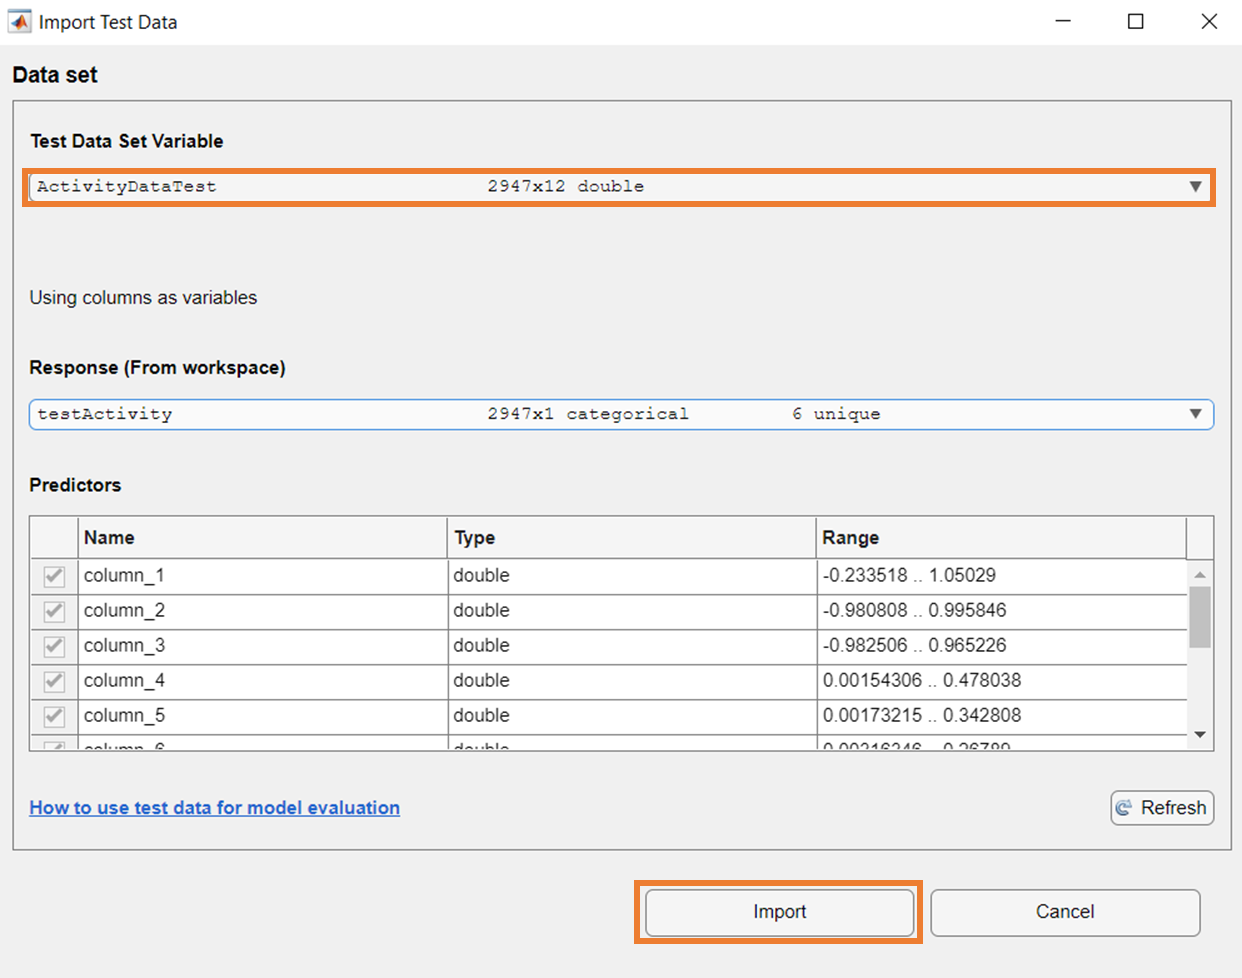

Elige un modelo cuyo rendimiento quieras evaluar haciendo clic en el botón de estrella (Agregar a favoritos) y luego en *Test Selected* seleccionado en el menú desplegable *Test All*. Alternativamente, no selecciones ningún modelo y haz clic en *Test All*. Al finalizar, la precisión en la ventana de Modelos cambiará a *Accuracy(Test)*. Tus resultados deberían verse similares a esto:

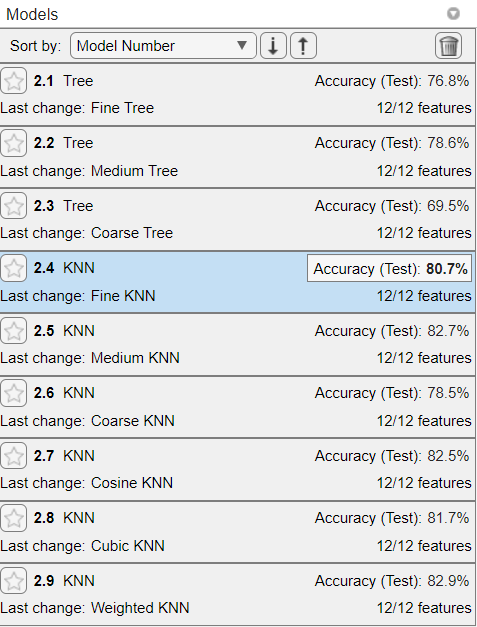

Puedes usar la matriz de confusión para visualizar en qué casos el modelo se equivocó con los datos de prueba.

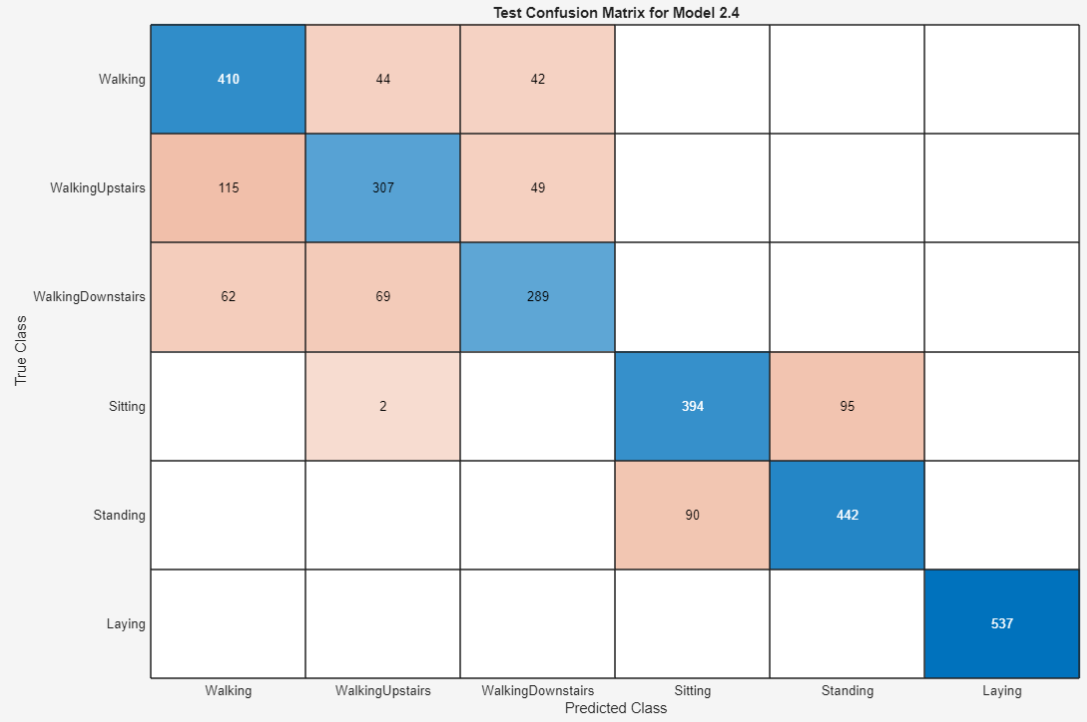

## Exportar el modelo

Puedes exportar tu modelo haciendo clic en *EXPORT* y seleccionando* Export model*. Si lo deseas, puedes cambiarle el nombre a tu modelo. El modelo entrenado aparecerá en el espacio de trabajo.

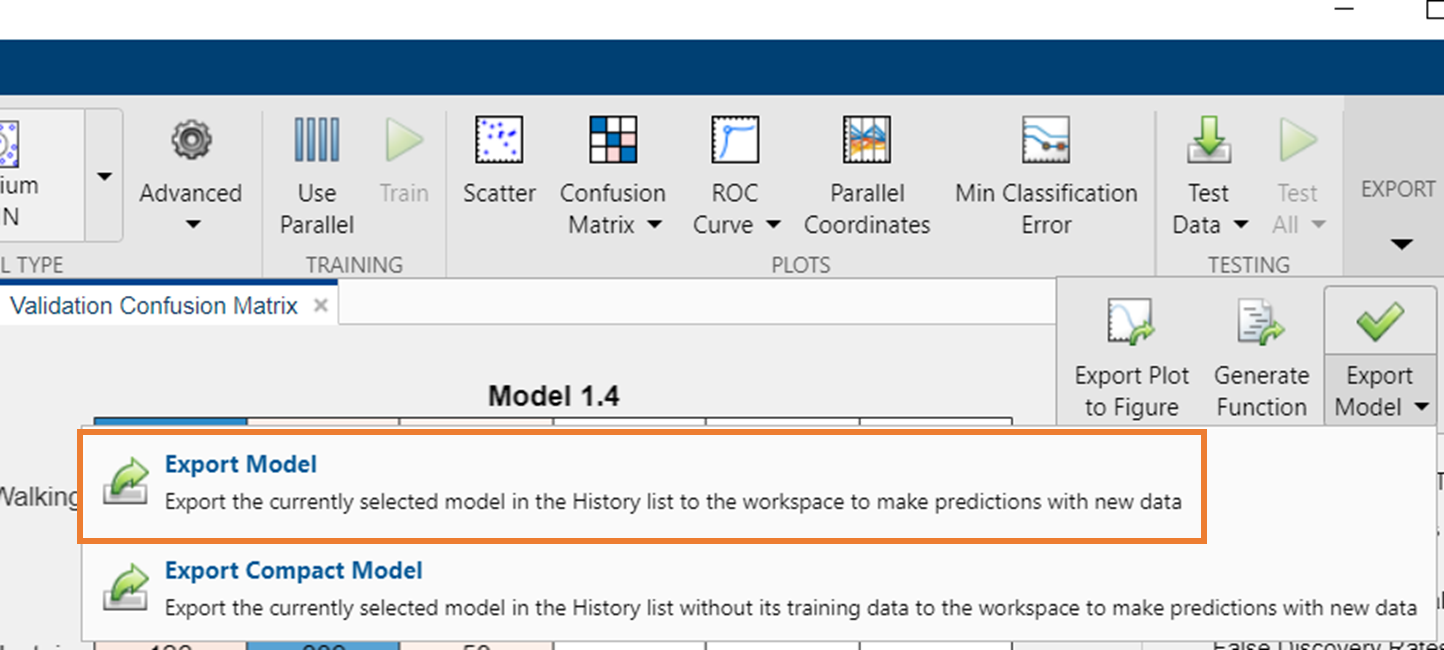

Hemos guardado un modelo entrenado anteriormente que llamamos `trainedModel``.`

load trainedModel.mat

Alternativamente, puedes generar una función para su uso posterior haciendo clic en *Generate Function* (se abrirá una nueva ventana con la función). La función generada también te muestra cómo se pueden realizar programáticamente los pasos descritos anteriormente. Generamos una para esta actividad que llamamos `trainClassifier.m . `Puedes entrenar el modelo utilizando el código en la siguiente línea.

[trainedClassifier, validationAccuracy] = trainClassifier(ActivityDataTrain,trainActivity)

trainedClassifier = struct with fields:
            predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2024b.'
          HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  [yfit,scores] = c.predictFcn(X) ↵replace 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 12 columns because this model was trained using 12 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'

validationAccuracy = 0.9120

Mostramos 

TestPredModel = trainedClassifier.predictFcn(ActivityDataTest);
accuracy = sum(testActivity==TestPredModel)/length(testActivity);
disp("Test Data Accuracy = "+100*accuracy+"%")

Test Data Accuracy = 76.6882%


## Resumen y siguientes pasos

En este ejemplo construimos modelos de aprendizaje automático para clasificar datos de actividad humana que fueron adquiridos desde un teléfono móvil. Extraímos características básicas aplicando medidas estadísticas, entrenamos de manera interactiva algunos modelos con la aplicación Classification Learner y comparamos su desempeño.

Claramente, no hemos resuelto este problema de manera satisfactoria, ya que la mayor precisión en los datos de prueba sigue estando alrededor del 81%. Aquí tienes algunos pasos adicionales que podrías intentar para mejorar la precisión:

- **Mejores características:** Aprovechando el conocimiento en procesamiento de señales, puedes extraer características más potentes. [Aquí ](https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/54139/versions/2/previews/html/DataClumsing.html)tienes un ejemplo que podrías usar.

- **Ajuste de hiperparámetros**: Cada modelo tiene parámetros que deben establecerse correctamente para lograr un rendimiento óptimo. [Aquí ](https://www.mathworks.com/help/stats/hyperparameter-optimization-in-classification-learner-app.html)tienes un ejemplo de cómo puedes optimizar los hiperparámetros dentro de la aplicación Classification Learner. Y [aquí ](https://www.mathworks.com/help/stats/bayesian-optimization-algorithm.html)tienes más información sobre cómo realizar Optimización Bayesiana. Alternativamente, podemos seleccionar automáticamente un modelo de clasificación con hiperparámetros optimizados usando la función "[fitcauto](matlab: web(fullfile(docroot, 'stats/fitcauto.html')))" para mejorar el rendimiento del clasificador. Puedes encontrar más información sobre AutoML [aquí](https://www.mathworks.com/discovery/automl.html).

- También puedes probar aprendizaje profundo (ver HumanActivityClassification_DL.mlx).

*Copyright 2025, The MathWorks, Inc.*